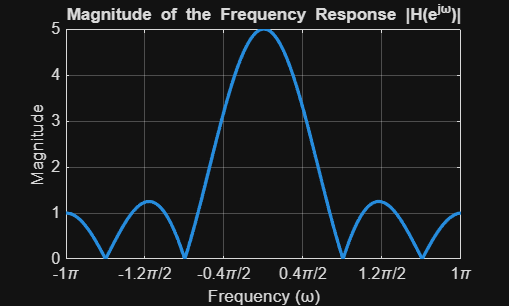

% Q. 1
% 1. Define the Impulse Response h[n]
h = [1, 1, 1, 1, 1];

% 2. Define the number of FFT points (for high resolution)
N_fft = 512;

% 3. Compute the DTFT (Frequency Response H(e^jw))
H_fft = fft(h, N_fft);

% 4. Center the DTFT spectrum (shift DC to center)
H_shifted = fftshift(H_fft);

% 5. Create the Frequency Axis (from -pi to pi for the plot data)
w = linspace(-pi, pi, N_fft);

% 6. Plot the Magnitude Response
figure;
plot(w, abs(H_shifted), 'LineWidth', 2);
title('Magnitude of the Frequency Response |H(e^{jω})|');
ylabel('Magnitude');
grid on;

% --- Commands to set the X-Axis Scale and Labels ---

% Define the desired range for the plot (X-Limits)
xlim([-pi pi]); 
xlabel('Frequency (ω)'); % Label remains ω

% 1. Define the locations of the tick marks in radians (multiples of pi/2)
% Go from -3pi to 3pi with steps of pi/2
tick_locations = -3*pi : 0.4*pi : 3*pi;
set(gca, 'XTick', tick_locations);

% 2. Define the labels to be displayed as text (e.g., -3\pi, -\pi/2)
% This creates a cell array of strings corresponding to the tick locations
labels = arrayfun(@(x) [num2str(x/pi), '\pi'], tick_locations, 'UniformOutput', false);

% Correct the labels to use the fraction form (e.g., -5\pi/2 instead of -2.5\pi)
for k = 1:length(tick_locations)
    if mod(tick_locations(k), pi) == 0 % Check for integer multiples of pi
        labels{k} = [num2str(tick_locations(k)/pi), '\pi'];
    else % For half-pi multiples
        labels{k} = [num2str(2*tick_locations(k)/pi), '\pi/2'];
    end
end

% Apply the new labels
set(gca, 'XTickLabel', labels);

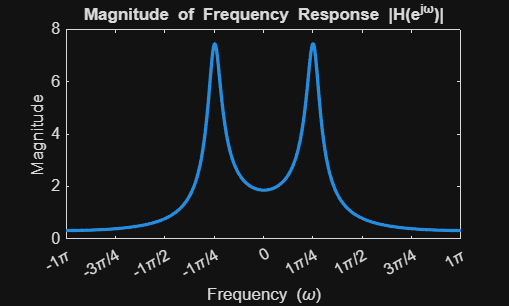

% Q. 4e
% Define the filter coefficients (from the simplified real-valued equation)
% Numerator B(z) = 1
b = [1]; 
% Denominator A(z) = 1 - 1.2728*z^-1 + 0.81*z^-2
a = [1, (-1*0.9*sqrt(2)), 0.81]; 

% Define the pole angle for visual marking
pole_angle = pi / 4;

% 1. Compute the Frequency Response
N_points = 512;
% freqz calculates H(e^jω) over [0, pi] by default
[H, w] = freqz(b, a, N_points, 'whole'); 

% 2. Center the Plot (shift DC from index 0 to the center)
H_shifted = fftshift(H);
w_shifted = linspace(-pi, pi, N_points);

% 3. Plot the Magnitude Response
figure;
plot(w_shifted, abs(H_shifted), 'LineWidth', 2);

% Add labels and grid
title('Magnitude of Frequency Response |H(e^{jω})|');
xlabel('Frequency (ω)');
ylabel('Magnitude');
xlim([-pi pi]); 
xlabel('Frequency (\omega)');

% 2. Define the locations of the tick marks in multiples of pi/4
% Go from -pi to pi with steps of pi/4
tick_locations = -pi : pi/4 : pi; 
set(gca, 'XTick', tick_locations);

% 3. Define the labels to be displayed as text (e.g., -\pi, -\pi/2, 0, \pi/2)
labels = cell(size(tick_locations)); % Initialize a cell array for text labels
for k = 1:length(tick_locations)
    % Simplify the display of the fraction
    if tick_locations(k) == 0
        labels{k} = '0';
    elseif abs(tick_locations(k)) == pi
        labels{k} = [num2str(tick_locations(k)/pi), '\pi'];
    elseif abs(tick_locations(k)) == pi/2
        labels{k} = [num2str(2*tick_locations(k)/pi), '\pi/2'];
    else
        % General case for pi/4, 3pi/4, etc.
        labels{k} = [num2str(4*tick_locations(k)/pi), '\pi/4'];
    end
end

% Apply the new labels
set(gca, 'XTickLabel', labels);